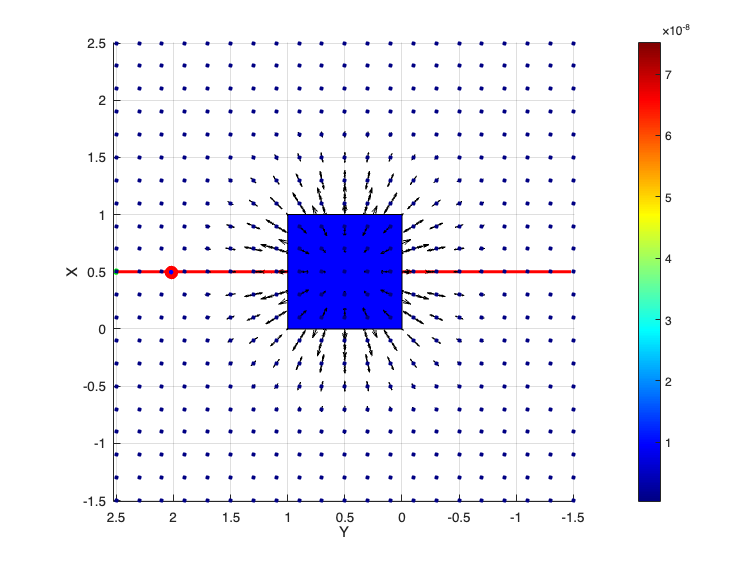

Eritrocito 1: tiene un desplazamiento dx asociado de: 0.000211


Eritrocito 1: x_final = 0.5042


Eritrocito 2: tiene un desplazamiento dx asociado de: 0.000600


Eritrocito 2: x_final = 0.5016


Eritrocito 3: tiene un desplazamiento dx asociado de: 0.000425


Eritrocito 3: x_final = 0.5043


Eritrocito 4: tiene un desplazamiento dx asociado de: 0.000474


Eritrocito 4: x_final = 0.5024


Eritrocito 5: tiene un desplazamiento dx asociado de: 0.000328


Eritrocito 5: x_final = 0.4967


Eritrocito 6: tiene un desplazamiento dx asociado de: 0.000020


Eritrocito 6: x_final = 0.4978


Eritrocito 7: tiene un desplazamiento dx asociado de: 0.000049


Eritrocito 7: x_final = 0.5032


Eritrocito 8: tiene un desplazamiento dx asociado de: 0.000198


Eritrocito 8: x_final = 0.5045


Eritrocito 9: tiene un desplazamiento dx asociado de: 0.000219


Eritrocito 9: x_final = 0.4988


Eritrocito 10: tiene un desplazamiento dx asociado de: 0.000497


%------------------------ Sistema de Unidades ------------------------%
% Longitud:      milímetros (mm)
% Tiempo:        segundos (s)
% Masa:          microgramos (µg)
% Carga:         Coulombs (C)
% Campo E:       Voltios por metro (V/m)
% Potencial V:   Voltios (V)
% Velocidad:     mm/s
% Fuerza:        microNewtons (µN)
% 
% NOTA:
% Se trabaja en un dominio tridimensional de ~1x1x1 mm³.
% Las cargas se expresan directamente en Coulombs.
% La masa de un eritrocito es ~27 picogramos ≈ 0.027 µg
% Se usan unidades SI adaptadas a microescala.

function mouseMoveCallback(~, ~)
    % Se ejecuta cuando el mouse se mueve
    % Puedes agregar más lógica aquí si necesitas hacer algo adicional
    drawnow;  % Refresca la visualización
end

vertices = [
    1, 1, 0;
    1, 0, 0;
    0, 0, 0;
    0, 1, 0;
    1, 1, 0.2;
    1, 0, 0.2;
    0, 0, 0.2;
    0, 1, 0.2;
    
    1, 1, 1;
    1, 0, 1;
    0, 0, 1;
    0, 1, 1;
    1, 1, 1.2;
    1, 0, 1.2;
    0, 0, 1.2;
    0, 1, 1.2;
];

% Valores extremos tridimensionales
min3d = -1.5;
max3d = 2.5;

faces = [
    1, 2, 3, 4;
    5, 6, 7, 8;
    1, 5, 6, 2;
    2, 6, 7, 3;
    3, 7, 8, 4;
    4, 8, 5, 1;

    9, 10, 11, 12;
    13, 14, 15, 16;
    9, 13, 14, 10;
    10, 14, 15, 11;
    11, 15, 16, 12;
    12, 16, 13, 9;
];

% Definir colores distintos para cada cara
colors = [
    1, 0, 0;  % Rojo
    1, 0, 0;
    1, 0, 0;
    1, 0, 0;
    1, 0, 0;
    1, 0, 0;

    0, 0, 1;  % Azul
    0, 0, 1;
    0, 0, 1;
    0, 0, 1;
    0, 0, 1;
    0, 0, 1;
];

resolution = 0.2;

% Preparar figura
figure;
hold on;
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z'); grid on;

% Vizualizacion y-z
view(-90, 90)
axis tight;

% Hacer el gráfico interactivo
set(gcf, 'WindowButtonMotionFcn', @mouseMoveCallback);  % Esto permite mover la vista mientras animas

% Dibujar las placas
patch('Faces', faces, 'Vertices', vertices, ...
      'FaceVertexCData', colors, 'FaceColor', 'flat', 'EdgeColor', 'k');

% Crear malla para campo
[xGrid, yGrid, zGrid] = meshgrid(min3d:resolution:max3d, min3d:resolution:max3d, min3d:resolution:max3d);

[Xc, Yc] = meshgrid(0:resolution:1, 0:resolution:1);

% Parámetros para distribución gaussiana
sigma = 0.25; % Controla qué tan concentradas están las cargas al centro
center = 0.5;

% Calcular pesos gaussianos
gaussian_weights = exp(-((Xc - center).^2 + (Yc - center).^2) / (2 * sigma^2));
gaussian_weights = gaussian_weights / max(gaussian_weights(:)); % Normalizar a 1

% Cargas con distribución espacial más realista
charges = [
    Xc(:), Yc(:), zeros(numel(Xc), 1),  1e-9 * gaussian_weights(:);
    Xc(:), Yc(:), ones(numel(Xc), 1), -1e-9 * gaussian_weights(:)
];

% Calcular potencial
V = zeros(size(xGrid));
for k = 1:size(charges, 1)
    r = bsxfun(@minus, cat(4, xGrid, yGrid, zGrid), reshape(charges(k, 1:3), 1, 1, 1, 3));
    R = sqrt(sum(r.^2, 4)) + 1e-6;
    V = V + charges(k,4) ./ R;
end

% Campo eléctrico = -grad(V)
[Ex, Ey, Ez] = gradient(-V, resolution);

% Calcular magnitud del campo eléctrico y su gradiente
E2 = Ex.^2 + Ey.^2 + Ez.^2;
[gradEx2, gradEy2, gradEz2] = gradient(E2, resolution);

% Dibujar campo eléctrico (quiver3)
quiver3(xGrid, yGrid, zGrid, Ex, Ey, Ez, 2, 'Color', 'k');

colormap jet;

% Crear un gráfico de dispersión para los colores
scatter3(xGrid(:), yGrid(:), zGrid(:), 10, E2(:), 'filled');  % Usamos 'E2' para determinar los colores
colorbar;  % Mostrar barra de color
clim([min(sqrt(E2(:))), max(sqrt(E2(:)))]);  % Ajustar la escala de colores al rango de magnitudes

% Simular eritrocitos
Ne = 50; % Numero de eritrocitos
h = 0.025; % Parametro ajustable
rad = 0.02; % Radio
m = 1e-12;     % masa del eritrocito [kg]
qe = 1e-6; % Carga del eritrocito en Coulombs
dt = 0.02; % Paso en el tiempo
Vy = 1; % Velocidad inicial en y
xmin = min(xGrid(:)); xmax = max(xGrid(:)); 
ymin = min(yGrid(:)); ymax = max(yGrid(:));
zmin = min(zGrid(:)); zmax = max(zGrid(:));

% Contador
healthy = 0; infected = 0;

% Datos estadisticos 
dx_totals = [];
categorias = [];
radios = [];

% Constante de Coulomb
ke = 8.9875517923e9;

% Determinar el maximo de pasos de simulacion por particula para prealocar
max_steps = floor(10 / dt) + 1;
posiciones_x = NaN(Ne, max_steps);  % [Ne x tiempo]
tiempo = NaN(Ne, max_steps);

% Lanzar 'n' eritrocitos con un parametro 'h' aleatorio entre 0.2 y 0.3
for i = 1:Ne
    if rand() < 0.5
        rad = 0.02;  % sano
        color = 'r';
    else
        rad = 0.025; % infectado (más grande)
        color = 'b';
    end

    dx = h*rand()*rad;
    fprintf('Eritrocito %d: tiene un desplazamiento dx asociado de: %f\n', i, dx);

    % Posición y velocidad inicial
    xEr = (max3d + min3d) / 2 + (rand() - 0.5) * 0.01; % Inicia en el centro con pequeña perturbacion
    yEr = min3d; % Inicia en el minimo del grafico
    zEr = (1 + 0.2)/2; % Este es el punto medio entre las dos placas

    pos = [xEr, yEr, zEr];
    vel = [0, Vy, 0];

    % Graficar eritrocito
    [xe, ye, ze] = sphere(10);
    eritr_plot = surf(rad*xe + pos(1), rad*ye + pos(2), rad*ze + pos(3), ...
                 'FaceColor', color, 'EdgeColor', 'none');

    % Crear el path o rastro del eritrocito
    path = animatedline('Color','r','LineWidth',1.5);
    head = scatter3(pos(1), pos(2), pos(3), 100, 'filled', 'r'); 

    x_traj = NaN(1, max_steps);

    % Simulación
    for t = 0:dt:10
    
        % Interpolar gradiente del campo
        gradE2 = [
            interp3(xGrid, yGrid, zGrid, gradEx2, pos(1), pos(2), pos(3), 'linear', 0), ...
            interp3(xGrid, yGrid, zGrid, gradEy2, pos(1), pos(2), pos(3), 'linear', 0), ...
            interp3(xGrid, yGrid, zGrid, gradEz2, pos(1), pos(2), pos(3), 'linear', 0)
        ];
        
        % Constante de proporcionalidad para fuerza DEP
        alpha = 1e-11;  % Ajustable, como una constante de Clausius-Mossotti simplificada
        acc = (alpha * rad^3 / m) * gradE2;
        
        % Actualizar velocidad y posición
        vel = vel + acc * dt;
        pos = pos + vel * dt;

        x_traj(floor(t/dt)+1) = pos(1);
        
        % Actualizar visualización
        set( eritr_plot, 'XData', rad*xe+pos(1), ...
                        'YData', rad*ye+pos(2), ...
                        'ZData', rad*ze+pos(3) );
        set( head,      'XData', pos(1), ...
                        'YData', pos(2), ...
                        'ZData', pos(3) );
        addpoints(path, pos(1), pos(2), pos(3));
        
        % Actualizar el grafico
        drawnow;

        % Romper si sale de los límites
        if any(pos < min3d) || any(pos > max3d)
            break;
        end
    end

    posiciones_x(i, :) = x_traj;

    % Borrar marcador para el siguiente eritrocito
    delete(head);

    % Clasificar según desplazamiento en x
    dx_total = abs(pos(1) - (max3d+min3d)/2);
    if dx_total > 0.002
        set(eritr_plot, 'FaceColor','g');  % sano
        healthy = healthy + 1;
    else
        set(eritr_plot, 'FaceColor','m');  % infectado
        infected = infected + 1;
    end

    fprintf('Eritrocito %d: x_final = %.4f\n', i, pos(1));

    % Guardar desplazamiento lateral
    dx_totals(i) = dx_total;
    
    % Categoría
    categorias(i) = double(rad == 0.02);  % 1 = sano, 0 = infectado
    
    % Radio
    radios(i) = rad;
    
    % Guardar tiempo real de trayectoria y posiciones
    tiempo_individual = 0:dt:t;
    num_samples = length(tiempo_individual);
    
    tiempo(i, 1:num_samples) = tiempo_individual;
    posiciones_x(i, 1:num_samples) = pos(1);  % Valor final repetido (puedes guardar trayectorias completas si haces seguimiento real)

end


%--- Resumen final ---%
fprintf('\nTotal sanos:     %d\n', healthy);
fprintf('Total infectados:  %d\n', infected);

% Histograma de desplazamientos
figure;
histogram(dx_totals, 'BinWidth', 0.001);
xlabel('dx [mm]');
ylabel('Frecuencia');
title('Distribución de desplazamiento lateral en X');

% Dispersión radio vs desplazamiento
figure;
scatter(radios, dx_totals, 50, categorias, 'filled');
xlabel('Radio [mm]');
ylabel('dx [mm]');
title('Relación entre radio y desplazamiento');
colorbar;

